# Automatic Flight Control of F8-Crusader

## Control Objective: 

To track a specific trajectory, $r\left(t\right)$, of the angle of attack, $x_1$.

## System: 

States: $x_1$ is the angle of attack (rad), $x_2$ is the pitch angle (rad), $x_3$ is the pitch rate (rad/s ) 

Control input: $u$ is the control input representing the tail deflection angle (rad)

Reference: $r\left(t\right)$ is the commanded angel of attack to be tracked

Outputs: assume full-state feedback (all states can be measured directly)

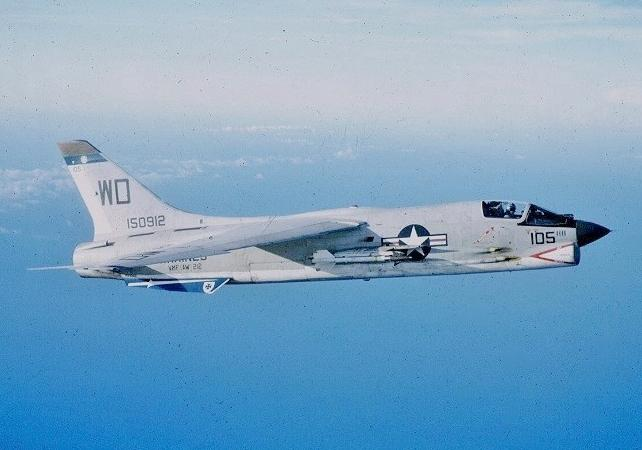

## Setting of Workflow

clear all, close all, clc;

figpath = './FIGURES/F8/';
datapath = './DATA/F8/';
paths = {figpath, datapath};

for p = 1:length(paths)
    if ~exist(paths{p}, 'dir')
        mkdir(paths{p});
    end
end

addpath('./utils/');
addpath('./EX_FLIGHT_CONTROL_F8/');

SystemModel = 'F8';
Nvar = 3; % number of states
Nctrl = 1; % number of control inputs

## Generating Training Data

InputSignalType = 'sine3'; % define type of control input to apply, u %'sine2'; sine3, %prbs; noise; sine2; sphs; 
ONLY_TRAINING_LENGTH = 1; % ?
ENSEMBLE_DATA = 0; % don't use ensemble learning methods
% generate training and validation data and plot control input and state
% time series
getTrainingData 

eps = 0;
u = u'; % control input time series

% Add noise
%eps = 0.05*std(x(:,1)); % define noise to add to true function values
%x = x + eps*randn(size(x));    

## SINDYc Modelling

We take $m$ ***snapshots*** in time of the state $\mathbf{x}$, the control input $\mathbf{u}$ and the time derivatives $\mathbf{\dot{x}}$:

$\mathbf{X} = [\mathbf{x_1} \quad \mathbf{x_2} \cdots \mathbf{x_m}] \in \mathbb{R}^{n \times m}$ , $\mathbf{U} = [\mathbf{u_1} \quad \mathbf{u_2} \cdots \mathbf{u_m}] \in \mathbb{R}^{p \times m}$ and $\mathbf{\dot{X}} = [\mathbf{\dot{x}_1} \quad \mathbf{\dot{x}_2} \cdots \mathbf{\dot{x}_m}] \in \mathbb{R}^{n \times m}$

where $n=3$ and $p=1$in our case.

We consider a ***library of candidate functions*** and evaluate it at $\mathbf{X}$and $\mathbf{U}$:


$$\mathbf{\Theta}(\mathbf{X}, \mathbf{U})$$


which will have $m$ rows corresponding to each snapshot in time, and in our case includes terms of the form $x_1^ax_2^bx_3^c$ for all combinations of powers $a,b,c = [0, 1, 2]$, where $\sigma$ is the number of canditate functions, which equals to $3*3*3 = 27$ in our case.

*English version: *We try to guess what sort of terms could be included in the true dynamic system $\mathbf{\dot{x}} = f(\mathbf{x}, \mathbf{u})$, find the value of these terms for the state and control input at each of our $m$ measurements over time, and put them all into a matrix $\mathbf{\Theta}$

We assume that the system can be modeled as a*** sparse linear combination*** of these candidate function:


$$\mathbf{\dot{X}} = \mathbf{\zeta} \mathbf{\Theta}^T(\mathbf{X}, \mathbf{U})$$


such that most of the coefficients $\mathbf{\zeta}$ are zero and their corresponding candidate term in $\mathbf{\Theta}$ is not included in the linear combination model.

These $k$th row of the coefficients matrix $\mathbf{\zeta}$, corresponding to the $k$th state in $\mathbf{\dot{x}}$ and the $k$th row in $\mathbf{\dot{X}}$ can be computed by minimizing the squared 2-norm error between the model and the measured values (first term) and minimizing the 1-norm of the coefficients to promote sparsity (second term).

*English version: *For each of our $m$ measurements of the state derivative $\mathbf{\dot{x}}$ in time, the $k \in [1, 2, \cdots, n]$th states across time can be approximated by $\dot{X}_k \approx \mathbf{\zeta}_k \theta^T(\mathbf{X}, \mathbf{U})$if we let most of the terms in $\mathbf{\zeta}_k$ go to zero. 


$$\mathbf{\zeta}_k = \arg\min_{\mathbf{\tilde{\zeta}}_k} \frac{1}{2}\Vert \mathbf{\dot{X}}_k - \mathbf{\tilde{\zeta}}_k \theta^T(\mathbf{X}, \mathbf{U}) \Vert_2^2 + \lambda \Vert \mathbf{\tilde{\zeta}}_k \Vert_1$$


*The Goal: *Find $\mathbf{\zeta}$ with many zero terms.

### Computing SINDYc model

% Parameters
ModelName = 'SINDYc';
savefile_SINDY = fullfile(datapath,['EX_',SystemModel,'_SI_',ModelName,'_',InputSignalType,'.mat']);
polyorder = 3; % define order of polynomial for library of canditate functions
usesine = 0; % ?
% lambda_vec = [.01,.01,0.1]; % sphs // WORKED IN MPC
lambda_vec = [.0001,.01,0.01]; % define sparsity regularization cnostants to test, sine2 // WORKED IN MPC   

if ~exists(savefile_SINDY)
% train the SINDYc model and return coefficients for each term in the
% library of canditate functions for each state
trainSINDYc

coefficients = 35×5 table
    Canditate Functions      xdot       ydot      zdot      udot
    ___________________    _________    ____    ________    ____

          {'1'  }                  0     0             0     0  
          {'x'  }             -0.877     0        -4.208     0  
          {'y'  }                  0     0             0     0  
          {'z'  }                  1     1        -0.396     0  
          {'u'  }             -0.215     0       -20.967     0  
          {'xx' }            0.46999     0      -0.46997     0  
          {'xy' }                  0     0             0     0  
          {'xz' }          -0.088006     0             0     0  
          {'xu' }                  0     0             0     0  
          {'yy' }             -0.019     0             0     0  
          {'yz' }      

### Predict State Values over Training Phase

% compute the state trajectory based on SINDYc model over training phase
if any(strcmp(InputSignalType,{'sine2', 'chirp','prbs', 'sphs'})==1)
    [tSINDYc, xSINDYc] = ode45(@(t,x) sparseGalerkinControl(t, x, forcing(x,t), Xi(:,1:Nvar), polyorder, usesine), tspan, x0,options);  % approximate
else
    p = struct;
    p.ahat = Xi(:,1:Nvar);
    p.polyorder = polyorder;
    p.usesine = usesine;
    p.dt = dt;
    [N,Ns] = size(x);
    xSINDYc = zeros(Ns,N); xSINDYc(:,1) = x0';
    for ct=1:N-1
        xSINDYc(:,ct+1) = rk4u(@sparseGalerkinControl_Discrete,xSINDYc(:,ct),u(ct),dt,1,[],p);
    end
    xSINDYc = xSINDYc'; % ?
end


### Plot State Values over Training Phase

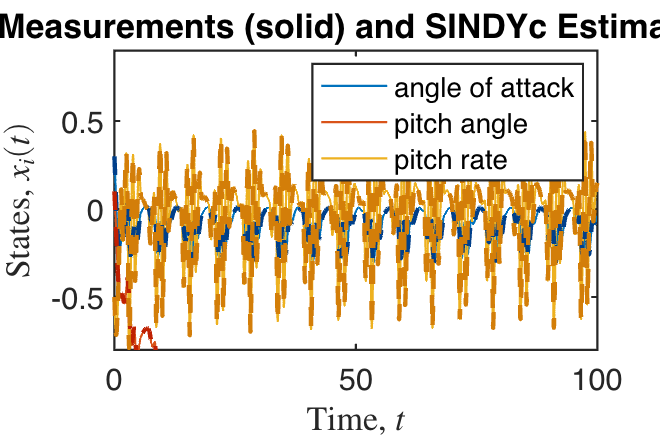

% setup figure
clear ph
figure, box on,
ccolors = get(gca,'colororder');
ccolors_valid = [ccolors(1,:)-[0 0.2 0.2];ccolors(2,:)-[0.1 0.2 0.09];ccolors(3,:)-[0.1 0.2 0.09]];

% plot the measurements of each state over time
for i = 1:Nvar
    ph(i) = plot(tspan, x(:,i),'-','Color',ccolors(i,:),'LineWidth',1); hold on
end

% plot the SINDYc estimates of each state over time
for i = 1:Nvar
    ph(Nvar+i) = plot(tspan, xSINDYc(:,i),'--','Color',ccolors_valid(i,:),'LineWidth',2);
end

ylim([-0.8 0.9])
xlabel('Time, $t$', 'Interpreter', 'latex')
ylabel('States, $x_i(t)$', 'Interpreter', 'latex')
title('Function Measurements (solid) and SINDYc Estimates (dashed)')
legend(ph([1,4]),'True',ModelName)
legend(ph([1,2,3]),'angle of attack','pitch angle', 'pitch rate')
set(gca,'LineWidth',1, 'FontSize',14)
set(gcf,'Position',[100 100 300 200])
set(gcf,'PaperPositionMode','auto')

print('-depsc2', '-loose', '-cmyk', [figpath,'EX_',SystemModel,'_SI_',ModelName,'_',InputSignalType,'.eps']);

### Predict State Values over Validation Phase

% Truth
tspanV   = [100:dt:200];
xA      = xv; % validation data
tA      = tv; % validation time phase

% Model
% compute the state trajectory based on SINDYc model over validation phase
if any(strcmp(InputSignalType,{'sine2', 'chirp','prbs', 'sphs'})==1)
    % predict system trajectory over validation time phase
    [tB, xB] = ode45(@(t,x) sparseGalerkinControl(t, x, forcing(x,t), Xi(:,1:Nvar), polyorder, usesine), tspanV, x(end,:), options);  % approximate
    xB = xB(2:end,:);
    tB = tB(2:end);  
else
    [N,Ns] = size(xA);
    xB = zeros(Ns,N); xB(:,1) = x(end,:)';
    for ct=1:N
        xB(:,ct+1) = rk4u(@sparseGalerkinControl_Discrete,xB(:,ct),uv(ct),dt,1,[],p);
    end
    xB = xB(:,1:N+1)';
    tB = tspanV(1:end);
end

### Plot Data over Training and Validation Phases

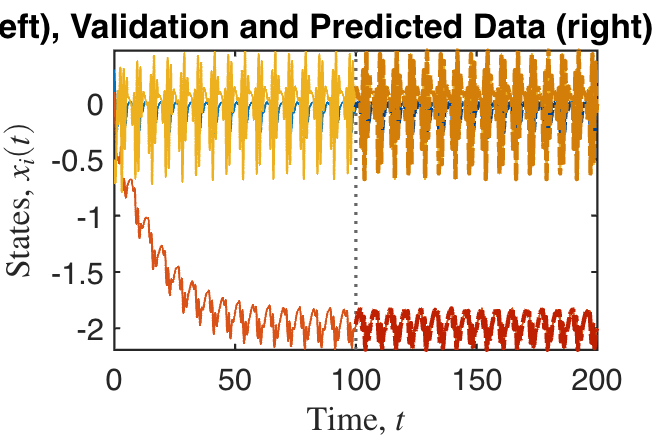

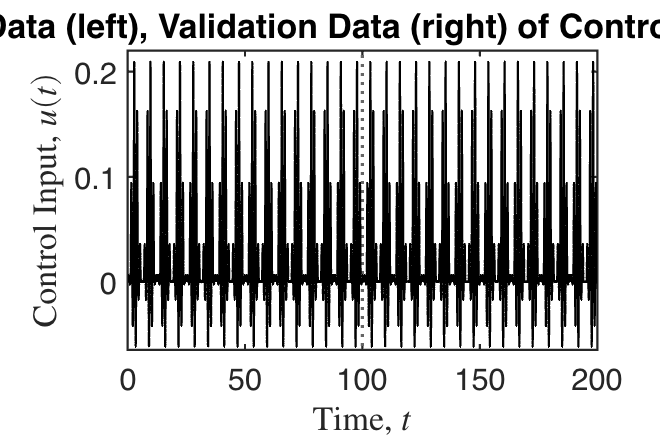

u = u';
VIZ_SI_Validation

### Save Data

Model_SINDY.name = 'SINDYc';
Model_SINDY.polyorder = polyorder;
Model_SINDY.usesine = usesine;
Model_SINDY.Xi = Xi;
Model_SINDY.dt = dt;
save(savefile_SINDY,'Model_SINDY')
else
    load(savefile_SINDY, 'Model_SINDY');
end

## DMDc Modeling

Again, we take $m$ ***snapshots*** in time of the state $\mathbf{x}$ and the control input $\mathbf{u}$:

$\mathbf{X} = [\mathbf{x_1} \quad \mathbf{x_2} \cdots \mathbf{x_{m-1}}] \in \mathbb{R}^{n \times (m-1)}$ and $\mathbf{U} = [\mathbf{u_1} \quad \mathbf{u_2} \cdots \mathbf{u_{m-1}}] \in \mathbb{R}^{p \times (m-1)}$ 

and we consider the snapshots of the subsequent states $\mathbf{x'}$:

 
$$\mathbf{X'} = [\mathbf{x_2} \quad \mathbf{x_2} \cdots \mathbf{x_{m}}] \in \mathbb{R}^{n \times (m - 1)}$$


where $n=3$ and $p=1$in our case.

We assume that the relationship between the $\mathbf{X'}$, $\mathbf{X}$ and $\mathbf{U}$ is linear:


$$\mathbf{X'} = \mathbf{A}\mathbf{X} + \mathbf{B}\mathbf{U} \in \mathbb{R}^{n \times m} $$


We best-fit solutions for$\mathbf{A}$ and $\mathbf{B}$ are found as:


$$[\mathbf{A}, \mathbf{B}] = \arg\min_{[\mathbf{\tilde{A}}, \mathbf{\tilde{B}}]} \frac{1}{2}\Vert \mathbf{X'} - \mathbf{\tilde{A}}\mathbf{X} - \mathbf{\tilde{B}}\mathbf{U}) \Vert_2^2$$


*The Goal: *Find $\mathbf{A}$ and $\mathbf{B}$

### Computing DMDc model


% Parameters
ModelName = 'DMDc';
Ndelay = 1;
savefile_DMD = fullfile(datapath,['EX_',SystemModel,'_SI_',ModelName,'_',InputSignalType,'.mat']);

if ~exists(savefile_DMD)
u = reshape(u, Nctrl, []);
Hu = getHankelMatrix_MV(u', Ndelay); % generate matrix of delayed control inputs st each row column corresponds to a time instance and each set of p rows to a delayed by k control input vector

xref = zeros(Nvar,1); % define the reference state
xmean = xref'; % define the mean state
X   = x - repmat(xmean,[length(tspan) 1]); % get the deviation from the reference state
Hx  = getHankelMatrix_MV(X, Ndelay); % generate matrix of delayed states st each row column corresponds to a time instance and each set of n rows to a delayed by k state vector

numOutputs = size(Hx,1); 
numInputs = size(Hu,1);

% choose ranks to truncate [X, U] SVD matrices (r1) and X' matrix at (r2)
r1 = numOutputs; 
r2 = numOutputs;

% compute best-fit A and B matrices using SVD decomposition
[sysmodel_DMDc, U, Up] = DelayDMDc_MV(Hx, Hu, r1, r2, dt, numOutputs, numInputs, 2); % is this correct

### Predict State Values over Training Phase

[xDMDc,~] = lsim(sysmodel_DMDc, Hu(1:end-1)', tspan(1:end-1), x(1,:)' -xmean');
xDMDc = xDMDc + repmat(xmean,[length(tspan)-1 1]);

### Plot State Values over Training Phase

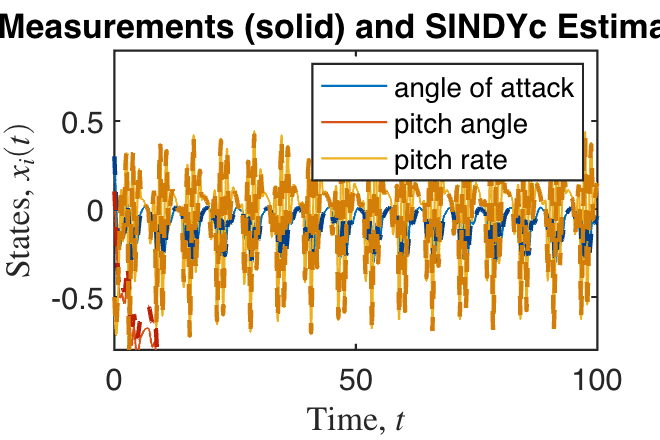

% setup figure
clear ph
figure,box on,
ccolors = get(gca,'colororder');
ccolors_valid = [ccolors(1,:)-[0 0.2 0.2]; ccolors(2,:)-[0.1 0.2 0.09]; ccolors(3,:)-[0.1 0.2 0.09]];

% plot the measurements of each state over time
for i = 1:Nvar
    ph(i) = plot(tspan, x(:,i),'-','Color', ccolors(i,:),'LineWidth',1); hold on
end

% plot the DMDc estimates of each state over time
for i = 1:Nvar
    ph(Nvar+i) = plot(tspan(Ndelay:length(tspan) - 1 + Ndelay - 1), xDMDc(:,i),'--','Color', ccolors_valid(i,:),'LineWidth',2);
end

xlim([0 (length(tspan)-1)*dt]), ylim([-0.8 0.8])
ylim([-0.8 0.9])
xlabel('Time, $t$', 'Interpreter', 'latex')
ylabel('States, $x_i(t)$', 'Interpreter', 'latex')
title('Function Measurements (solid) and SINDYc Estimates (dashed)')
legend(ph([1,3]),'True', ModelName)
legend(ph([1,2,3]),'angle of attack','pitch angle', 'pitch rate')
set(gca,'LineWidth',1, 'FontSize', 14)
set(gcf,'Position',[100 100 300 200])
set(gcf,'PaperPositionMode','auto')

print('-depsc2', '-loose', '-cmyk', [figpath,'EX_', SystemModel,'_SI_', ModelName,'_', InputSignalType,'.eps']);

### Predict State Values over Validation Phase

% Truth
tspanV   = [100:dt:200];
xA      = xv; % validation data
tA      = tv; % validation time phase

% Model
% compute the state trajectory based on DMDc model over validation phase
if Ndelay == 1
    x0      = [x(end,1:3)];
    Hunew   = [u(end), uv(1:end)];
    % predict system trajectory over validation time phase
    [xB,tB] = lsim(sysmodel_DMDc, Hunew, tspanV, [x0 - [xmean]]');
elseif Ndelay > 1
    x0      = [x(end - Ndelay + 1, 1:3), x(end,1:3)];
    Hunew   = [u(end - Ndelay + 1:end), uv(1:end-Ndelay);
        u(end), uv(1:end-1)];
    [xB,tB] = lsim(sysmodel_DMDc, Hunew, tspanV, [x0 - [xmean]]');
    xB = xB(:,4:6); 
    xB = xB + repmat(xref,[size(xB,1) 1]);
end

xB = xB + repmat(xmean,[length(tB) 1]);

### Plot Data over Training and Validation Phases

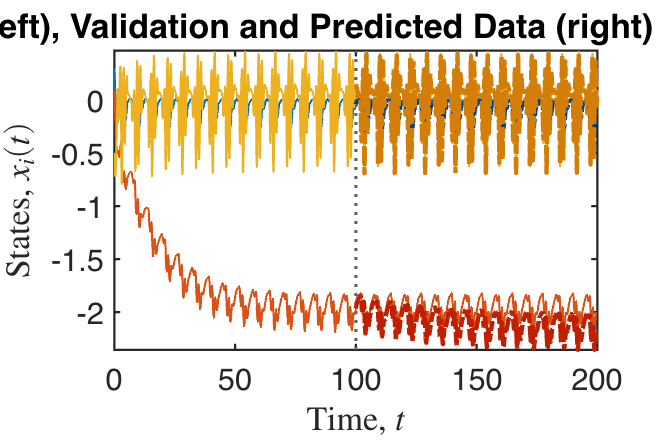

VIZ_SI_Validation

### Save Data

Model_DMD.name = 'DelayDMDc';
Model_DMD.sys = sysmodel_DMDc;
Model_DMD.Ndelay = Ndelay;
Model_DMD.xmean = xmean;
Model_DMD.xrefs = xref;
Model_DMD.dt = dt;
save(savefile_DMD,'Model_DMD');
else
    load(savefile_DMD, 'Model_DMD');
end

## MPC Simulation